# Problem Set 2: Poisson Spiking

CPNS 35600, Mia Paletta, Spring 2021

## P1: Compute variance of a Poisson Process

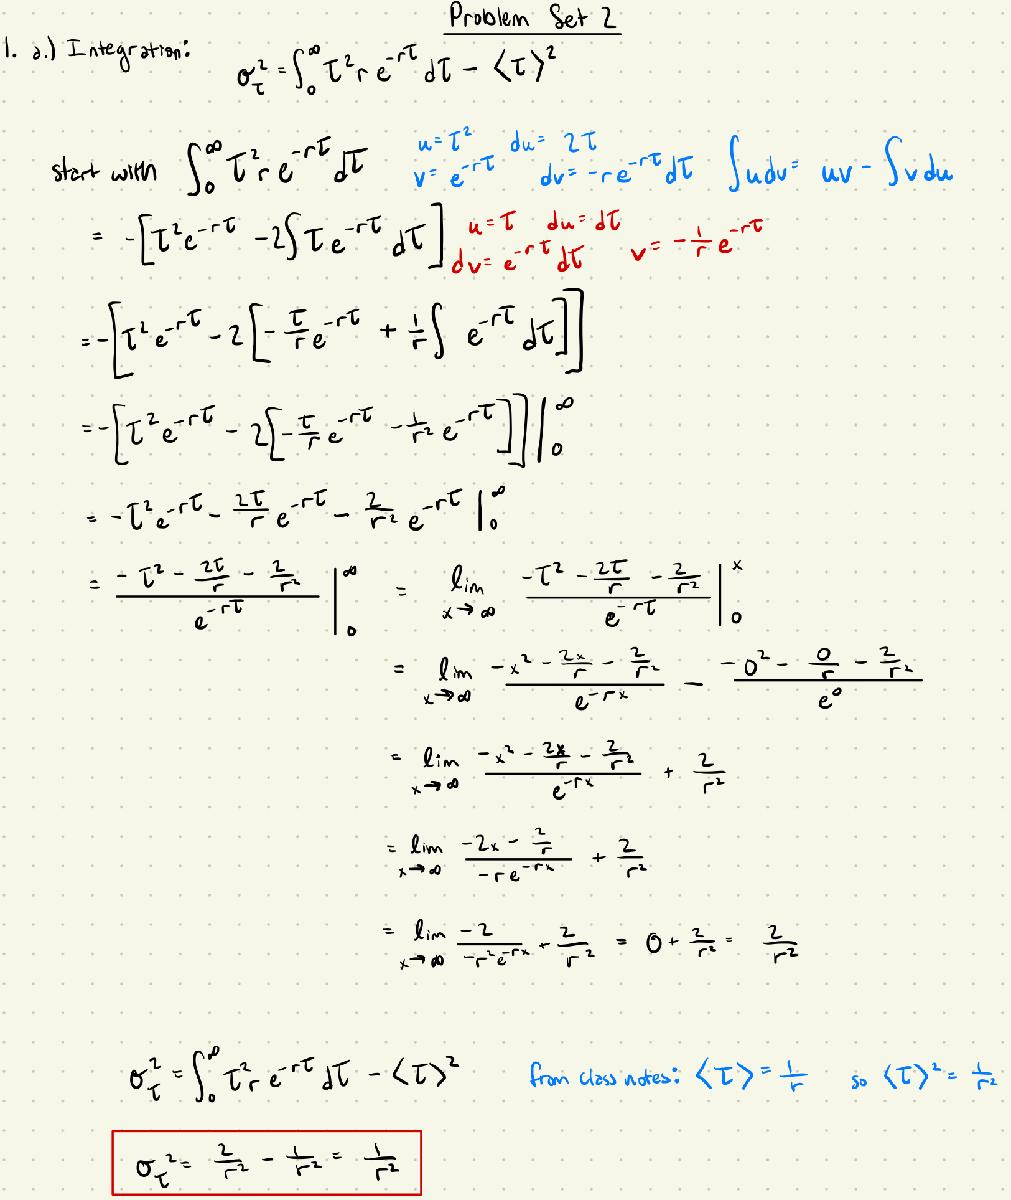

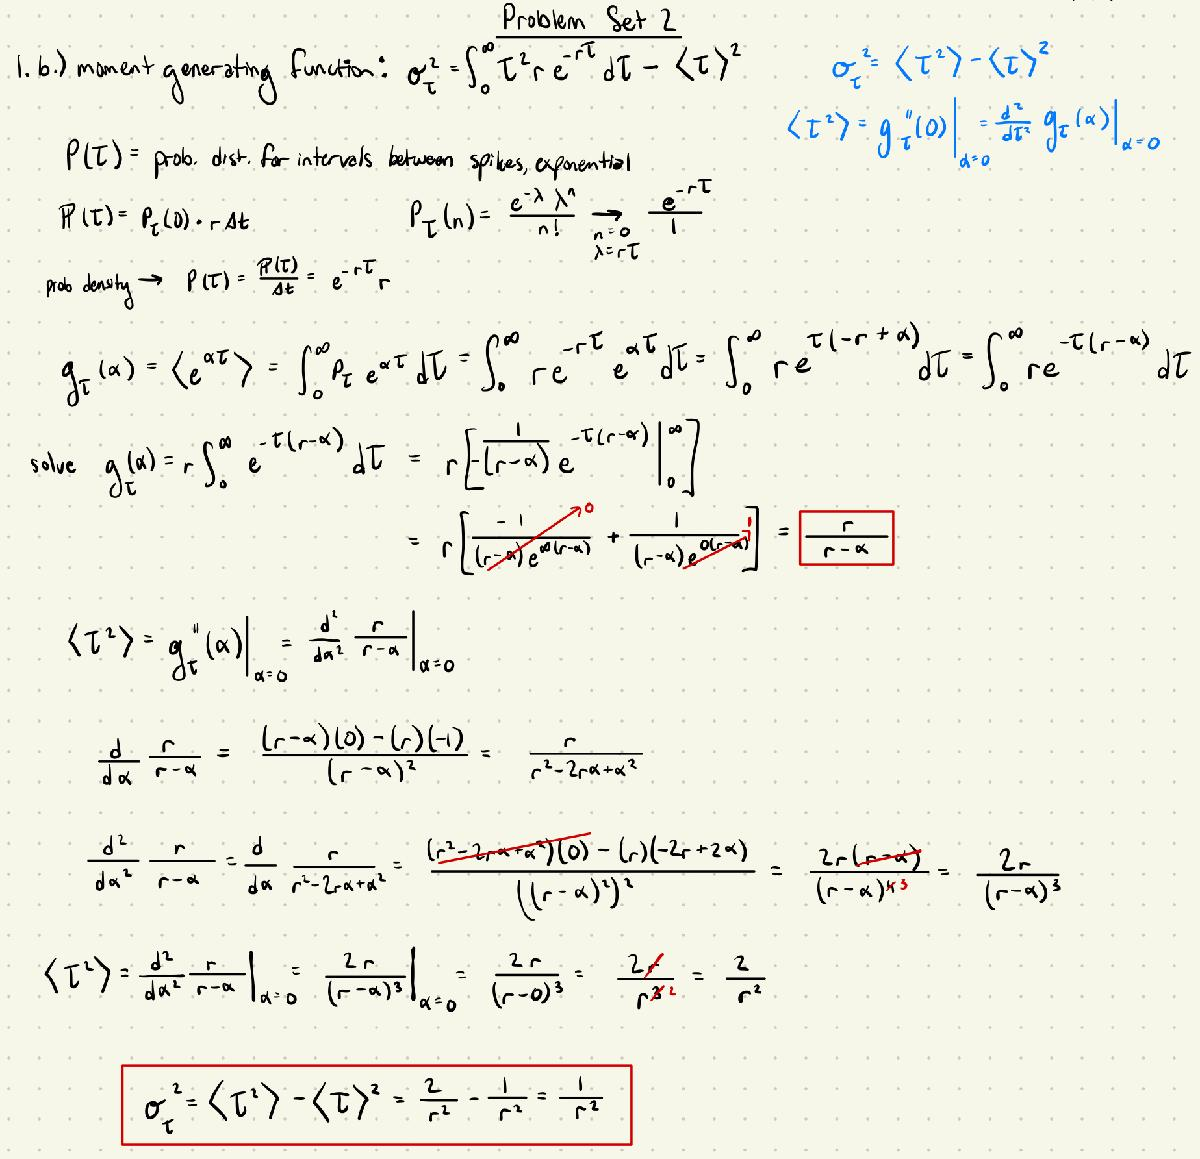

## P2: Generating Poisson spike trains

- estimated firing rate: $r_{\textrm{est}} \left(t\right)$

- probability of firing a spike in a short interval: $r_{\textrm{est}} \left(t\right)\Delta t$

- For each bin, generate a random number $x_{\textrm{rand}}$ uniformly from 0 to 1

- Spike fired if $r_{\textrm{est}} \left(t\right)\Delta t$ > $x_{\textrm{rand}}$

- Generate spikes for at least 10s

- constant rate: 100spikes/s

- Histogram of ISI, FF and CV for several counting intervals: 1, 10, 50, 100ms.

- $\textrm{CV}=\frac{\sigma_{\tau } }{\left\langle \tau \right\rangle }$ where $\left\langle \tau \right\rangle =\frac{1}{r}$

- FF = $\frac{{\sigma_n }^2 }{\left\langle n\right\rangle }$

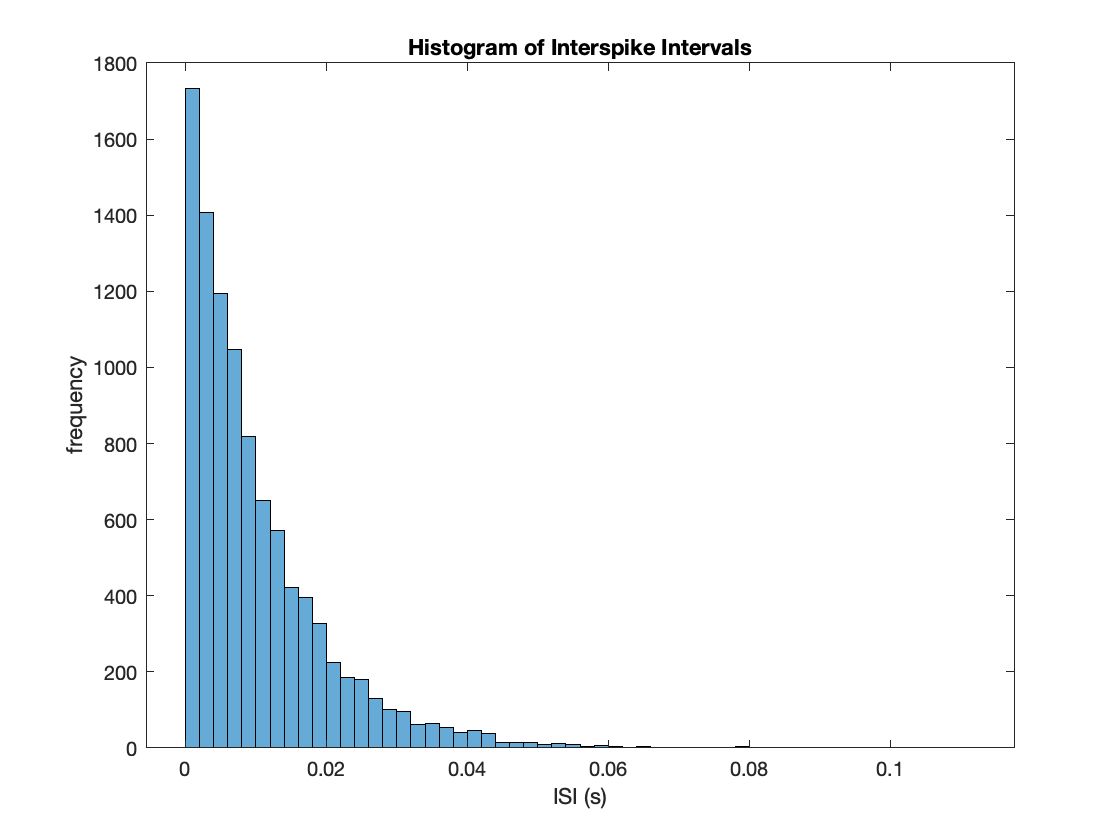

% generate Poisson spikes

time_interval = 100; % 10s time interval for spikes
delta_t = 0.0001; % 0.1ms bins
r_est = 100; % spikes/s

x_rand = rand(1, time_interval / delta_t);
spike_mask = (r_est * delta_t) >= x_rand; %find where spikes occur
binned_spikes = double(spike_mask); %create binned spikes

bin_times = 0+delta_t:delta_t:time_interval; %find time in s for each bin
spike_times = bin_times(spike_mask);
ISIs = diff(spike_times);

figure
histogram(ISIs);
title('Histogram of Interspike Intervals')
xlabel('ISI (s)')
ylabel('frequency')

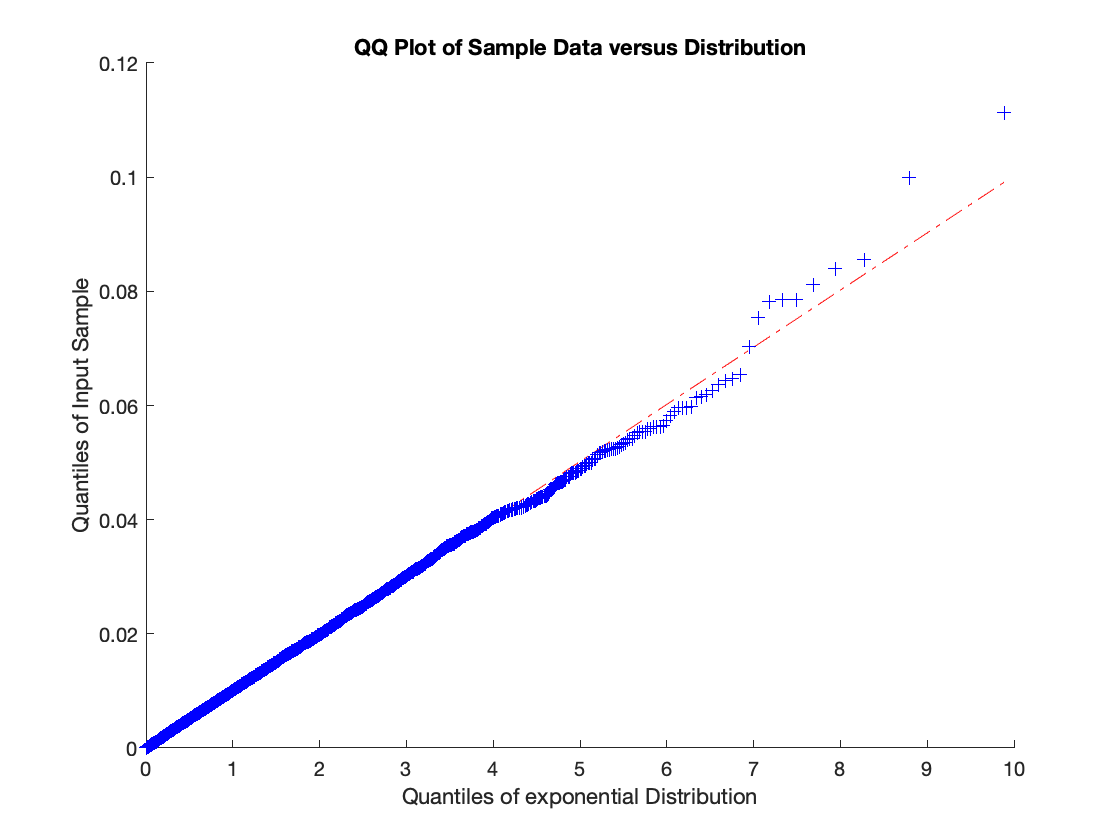



% see how well ISIs fit an exponential distribution, which we expect
pd = makedist("Exponential");

figure
qqplot(ISIs, pd)

**From the QQ plot, we can see that our interspike intervals fit an exponential distribution quite well with the exception of a few larger values in the tail of the distribution. We expect this result given that the intervals between Poisson events should be exponentially distributed.**

% calculate CV of ISIs

CV_ISI = std(ISIs) / mean(ISIs) %stdev of ISIs over their expected value

CV_ISI = 0.9859



% FF of spike counts for various counting intervals

% 1ms counting interval - every 10 bins
spike_counts_1 = [];

for i = 1:(length(binned_spikes)/10)
    interval_count = sum(binned_spikes(10*(i-1) + 1:10*i));
    spike_counts_1 = [spike_counts_1 interval_count];
end

FF_1 = var(spike_counts_1) / mean(spike_counts_1)

FF_1 = 0.9939



% 10ms counting interval - every 100 bins
spike_counts_10 = [];

for i = 1:(length(binned_spikes)/100)
    interval_count = sum(binned_spikes(100*(i-1) + 1:100*i));
    spike_counts_10 = [spike_counts_10 interval_count];
end

FF_10 = var(spike_counts_10) / mean(spike_counts_10)

FF_10 = 0.9747



% 50ms counting interval - every 500 bins
spike_counts_50 = [];

for i = 1:(length(binned_spikes)/500)
    interval_count = sum(binned_spikes(500*(i-1) + 1:500*i));
    spike_counts_50 = [spike_counts_50 interval_count];
end

FF_50 = var(spike_counts_50) / mean(spike_counts_50)

FF_50 = 0.9752



% 100ms counting interval - every 1000 bins
spike_counts_100 = [];

for i = 1:(length(binned_spikes)/1000)
    interval_count = sum(binned_spikes(1000*(i-1) + 1:1000*i));
    spike_counts_100 = [spike_counts_100 interval_count];
end

FF_100 = var(spike_counts_100) / mean(spike_counts_100)

FF_100 = 1.0138

## P3: Adding a refractory period

% generate spikes with a refractory period

tau_ref = 0.001:0.001:0.02; % 1ms to 20ms in 1ms increments

for tau = 1:length(tau_ref)
    tau_binned_spikes = zeros(1, time_interval / delta_t);
    r_0 = 100; % spikes/s
    r = r_0; % initialize the firing rate at 100spikes/s

    for i = 1:length(tau_binned_spikes)
        spike_check = (r * delta_t) > rand;
        tau_binned_spikes(i) = double(spike_check);
        if spike_check == 1
            r = 0;
        else
            r = r + (((r_0 - r) * delta_t) / tau_ref(tau));
        end
    end
    ref_binned_spikes{tau} = tau_binned_spikes;
    ref_spike_mask{tau} = ref_binned_spikes{tau} == 1;
    ref_spike_times{tau} = bin_times(ref_spike_mask{tau});
    ref_ISIs{tau} = diff(ref_spike_times{tau});
end

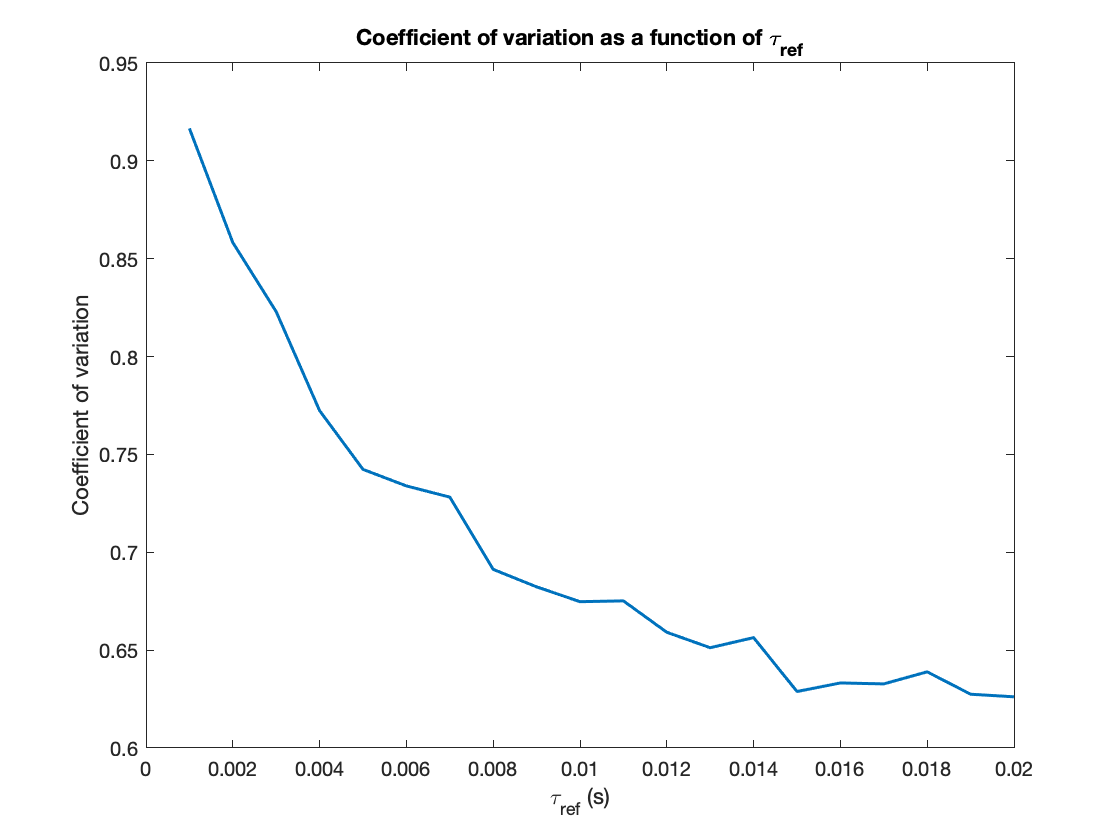

% find coefficient of variation for each value of tau
ref_CV = [];

for i = 1:length(ref_ISIs)
    ref_CV(i) = std(ref_ISIs{i}) / mean(ref_ISIs{i});
end

figure
plot(tau_ref, ref_CV, 'LineWidth', 1.5)
title('Coefficient of variation as a function of \tau_{ref}')
xlabel('\tau_{ref} (s)')
ylabel('Coefficient of variation')

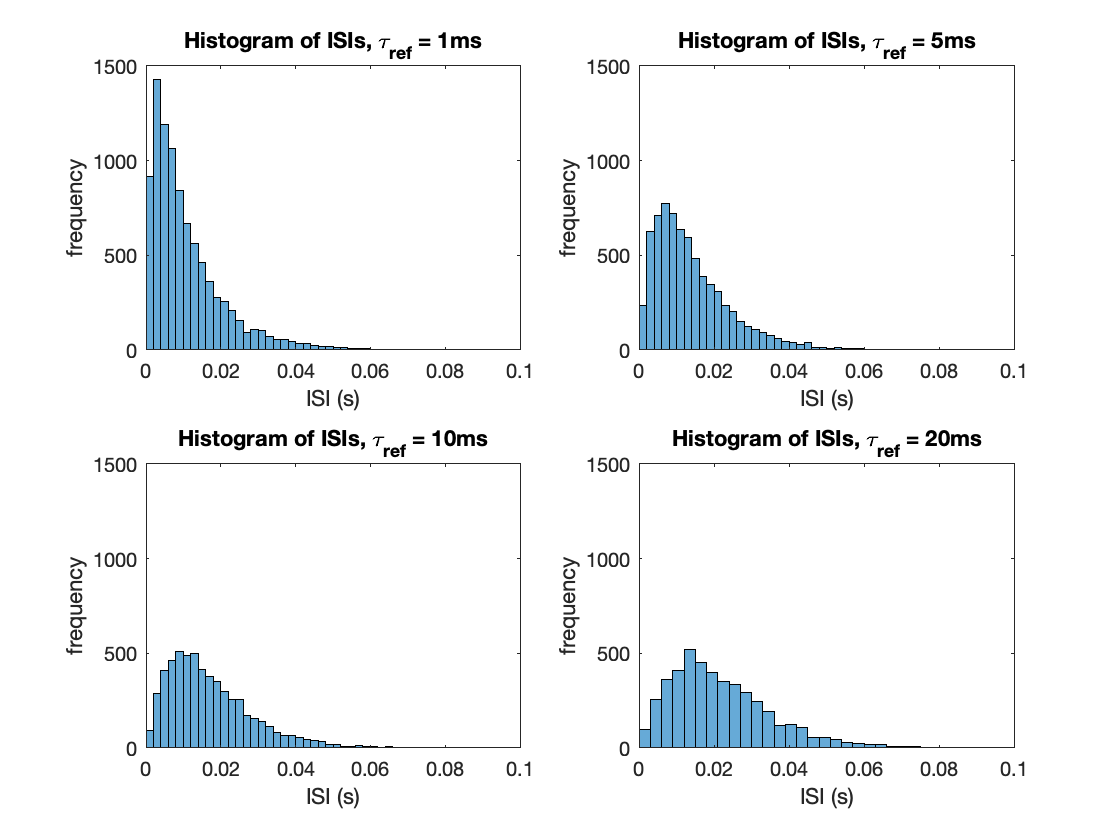

% plot some ISI histograms
ISI_inds = [1 5 10 20];

figure
for i = 1:4
    subplot(2, 2, i)
    histogram(ref_ISIs{ISI_inds(i)})
    title(sprintf('Histogram of ISIs, \\tau_{ref} = %dms', ISI_inds(i)))
    xlabel('ISI (s)')
    ylabel('frequency')
    xlim([0 0.1])
    ylim([0 1500])
end

% compute FF for various counting intervals where tau_ref = 10ms

tau10_ref_spikes = ref_binned_spikes{10};

% 1ms counting interval - every 10 bins
ref_spike_counts_1 = [];

for i = 1:(length(tau10_ref_spikes)/10)
    interval_count = sum(tau10_ref_spikes(10*(i-1) + 1:10*i));
    ref_spike_counts_1 = [ref_spike_counts_1 interval_count];
end

ref_FF_1 = var(ref_spike_counts_1) / mean(ref_spike_counts_1)

ref_FF_1 = 0.9453



% 10ms counting interval - every 100 bins
ref_spike_counts_10 = [];

for i = 1:(length(tau10_ref_spikes)/100)
    interval_count = sum(tau10_ref_spikes(100*(i-1) + 1:100*i));
    ref_spike_counts_10 = [ref_spike_counts_10 interval_count];
end

ref_FF_10 = var(ref_spike_counts_10) / mean(ref_spike_counts_10)

ref_FF_10 = 0.6672



% 50ms counting interval - every 500 bins
ref_spike_counts_50 = [];

for i = 1:(length(tau10_ref_spikes)/500)
    interval_count = sum(tau10_ref_spikes(500*(i-1) + 1:500*i));
    ref_spike_counts_50 = [ref_spike_counts_50 interval_count];
end

ref_FF_50 = var(ref_spike_counts_50) / mean(ref_spike_counts_50)

ref_FF_50 = 0.4892


% 100ms counting interval - every 1000 bins
ref_spike_counts_100 = [];

for i = 1:(length(tau10_ref_spikes)/1000)
    interval_count = sum(tau10_ref_spikes(1000*(i-1) + 1:1000*i));
    ref_spike_counts_100 = [ref_spike_counts_100 interval_count];
end

ref_FF_100 = var(ref_spike_counts_100) / mean(ref_spike_counts_100)

ref_FF_100 = 0.5049

## P4: Poisson Paradox

**If we consider a Poisson distributed spike train with a constant rate, the likelihood of an event happening at any time step (meaning, the likelihood of a spike occurring in any given time bin) is identical. Additionally, these events are entirely independent, so the presence or absence of a spike in any given bin does not change the likelihood of one occurring in any subsequent bin. Essentially, this means that an event is equally likely to occur in any bin. It is easy to believe that if we see many spikes in the beginning of an interval, we will then not see a spike. However, simply believing that because we've seen an event happen many times we will then not see an event is an example of the gambler's fallacy. A classical example of this would be a coin flip. If we flip a fair coin 4 times in a row and get heads each time, many people would expect the next flip to be tails. However, this is untrue--the probability of heads or tails has not changed, and they are still equally likely because the events are indepedent. Simply expecting not to see a spike because you've seen many in a row is no different, though it is mathematically true in our previous questions that it would be unusual to see many spikes in a sequence.**

**If we have a rate of 100spikes/s and a bin size of 0.0001s as we do in P2, we have a 1% chance for every bin that we will see a spike. So, because events are independent, the probability of seeing two spikes in a row would be (0.01)*(0.01) = 0.0001 or 0.01%. For three consecutive spikes, it would be (0.01)*(0.01)*(0.01) = 0.000001 or 0.0001%. So, the probability of many unlikely independent events happening in sequence is quite low, but it is important for our intuitions about probability to be based on the math itself rather than fallacies.**

## P5: Time-varying Poisson Process

% load the data

MT = load("cell14l07_for_class.mat"); %saved to struct to avoid overwriting vars above

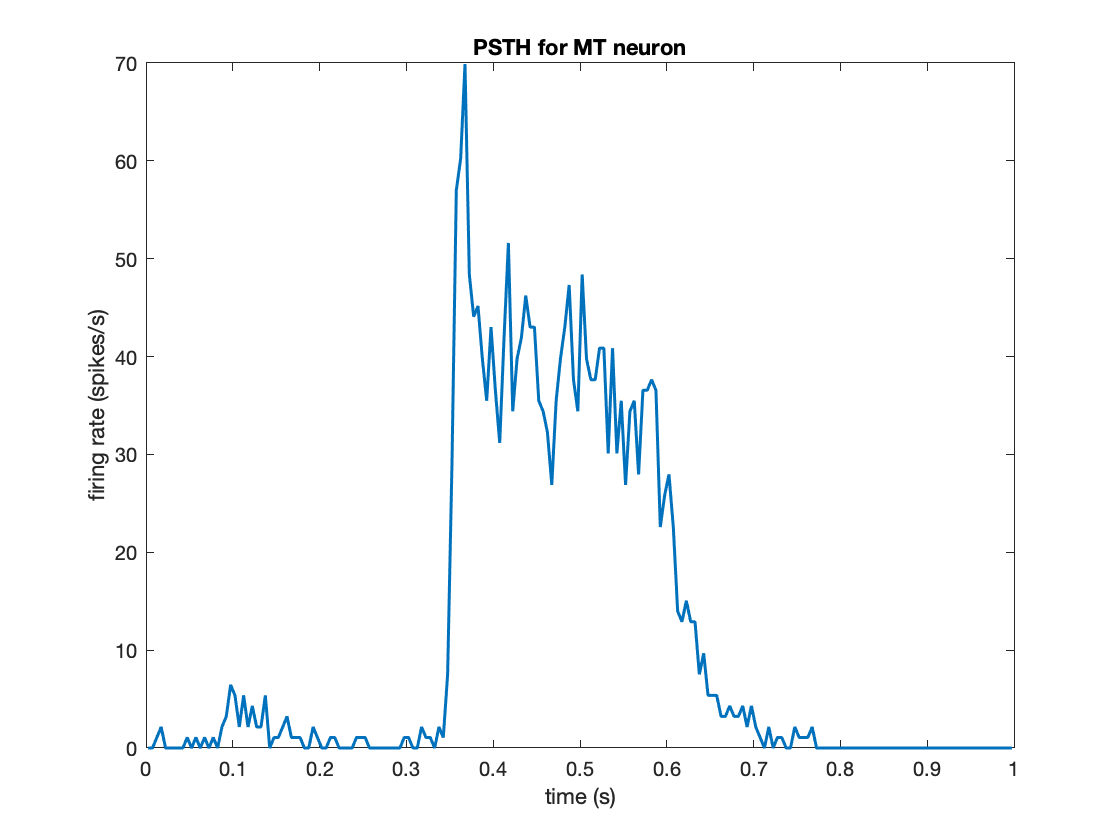

% bin the spikes  - use a 5ms bin

MT_bin_length = 5; % 5ms bin length
edges = 0:MT_bin_length:1000;
MT_binned_spikes = zeros(length(edges)-1, length(MT.spike_times));

for i = 1:length(MT.spike_times)
    MT_binned_spikes(:, i) = histcounts(MT.spike_times{i}, edges)';
end

% trial average the binned spike counts
MT_tr_avg_spikes = mean(MT_binned_spikes, 2);

% convert to firing rate by dividing by bin length
MT_avg_fr = MT_tr_avg_spikes / (MT_bin_length / 1000); % spikes/s

MT_avg_var = var((MT_binned_spikes ./ (MT_bin_length/1000)),[], 2);

% plot a PSTH
bin_centers = (edges(1:end-1) + 2.5) / 1000;

figure
plot(bin_centers, MT_avg_fr, "LineWidth", 1.5)
xlabel('time (s)')
ylabel('firing rate (spikes/s)')
title('PSTH for MT neuron')

**Used a 5ms bin size**

% generate a Poisson model with the rates from the real neuron

time_interval = 1; % 1s time interval for spikes
delta_t = 0.0001; % 0.1ms bins

% create vec of rates that is same length as our number of bins and scale
rate_vec = repelem(MT_avg_fr, 50);

Poisson_model_FR = [];

for tr = 1:size(MT_binned_spikes,2)
    % generate the model spikes with the real rates
    MT_model_spikes = zeros(1,length(rate_vec));
    
    for i = 1:length(rate_vec)
        MT_model_spikes(i) = double((rate_vec(i) * delta_t) > rand);
    end
    
    % bin the model spikes
    model_scs = [];
    
    for i = 1:(length(MT_model_spikes)/50)  % 5ms counting interval - every 50 bins
        interval_count = sum(MT_model_spikes(50*(i-1) + 1:50*i));
        model_scs = [model_scs interval_count];
    end
    
    % convert scs to fr - divide by 5ms bin size
    model_frs = model_scs / 0.005;
    
    Poisson_model_FR = [Poisson_model_FR model_frs'];
end

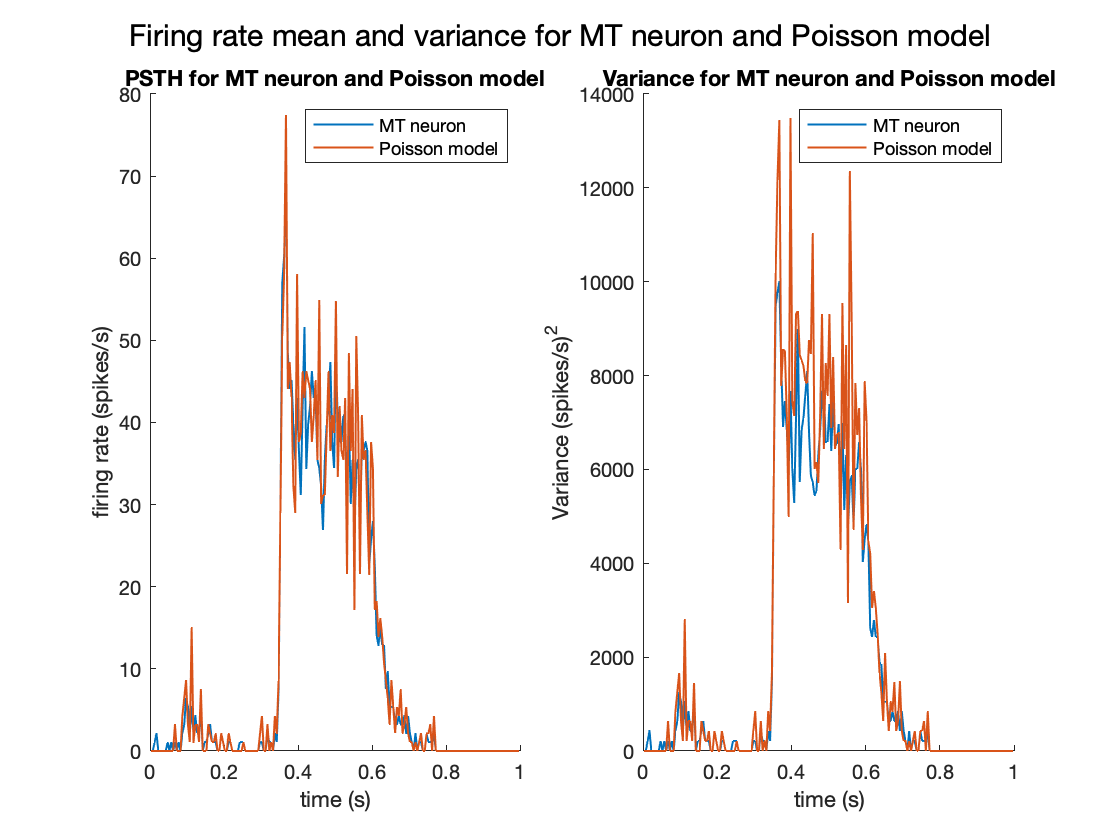

% find trial avg FR and variance for the model and real data

% find model mean (trial averaged FR)
Poisson_model_tr_avg_FR = mean(Poisson_model_FR, 2);

% find model variance
Poisson_model_avg_var = var(Poisson_model_FR, [], 2);

figure
subplot(1,2,1)
hold on
plot(bin_centers, MT_avg_fr, "LineWidth", 1)
plot(bin_centers, Poisson_model_tr_avg_FR, "LineWidth", 1)
xlabel('time (s)')
ylabel('firing rate (spikes/s)')
title('PSTH for MT neuron and Poisson model')
legend('MT neuron', 'Poisson model')

subplot(1,2,2)
hold on
plot(bin_centers, MT_avg_var, "LineWidth", 1)
plot(bin_centers, Poisson_model_avg_var, "LineWidth", 1)
xlabel('time (s)')
ylabel('Variance (spikes/s)^2')
title('Variance for MT neuron and Poisson model')
legend('MT neuron', 'Poisson model')

sgtitle('Firing rate mean and variance for MT neuron and Poisson model')

**From these plots, we can see that the mean and variance of the firing rate for the model data does capture the real neuron's behavior fairly well, but the model does have some more extreme values. The genereal shape of the PSTH and variance over time are similar, but the modeled data has sharper, larger peaks.**